clear; close all; clc;

% slip angle vector
alpha = 0:0.1:12;

% load vectors
Fz1 = 300*ones(size(alpha));
Fz2 = 500*ones(size(alpha));
Fz3 = 700*ones(size(alpha));

% collect input vectors
X1 = [alpha', Fz1'];
X2 = [alpha', Fz2'];
X3 = [alpha', Fz3'];


## Parameters

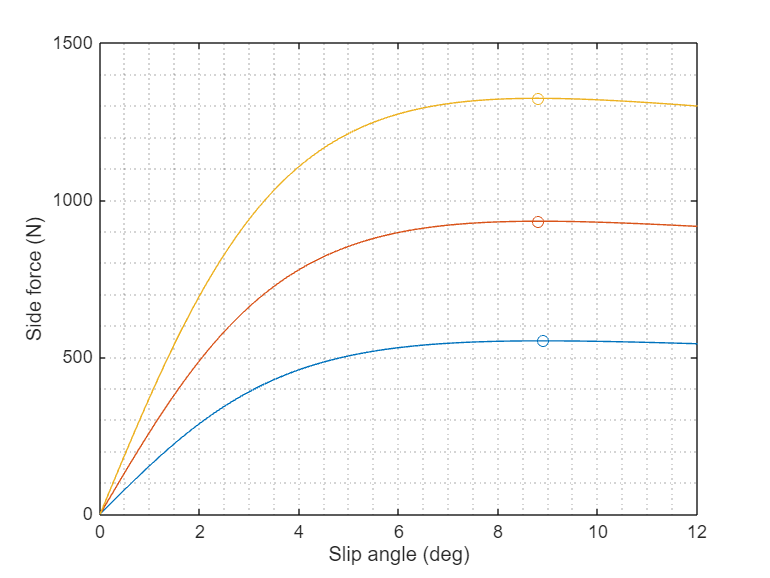

D1 = 1.37;
D2 = 0.13;
B  = 0.19;
C  = 1.51;
Bp = 0.02;
Sv = 0;

% collect in array
P = [D1, D2, B, C, Bp, Sv];

% calculate outputs
out1 = Pacejka5_model(P, X1);
out2 = Pacejka5_model(P, X2);
out3 = Pacejka5_model(P, X3);

% plot result
figure('Name', 'Slip angle curves'); hold all; box on;
plot(alpha, out1);
plot(alpha, out2);
plot(alpha, out3);
%xline(0, 'k-'); yline(0, 'k-');
grid minor;
xlabel('Slip angle (deg)');
ylabel('Side force (N)');
xlim([0 12]);
ylim([0 1500]);

idx1 = out1 == max(out1);
idx2 = out2 == max(out2);
idx3 = out3 == max(out3);

plot(alpha(idx1), out1(idx1), 'o', 'Color', "#0072BD");
plot(alpha(idx2), out2(idx2), 'o', 'Color', "#D95319");
plot(alpha(idx3), out3(idx3), 'o', 'Color', "#EDB120");